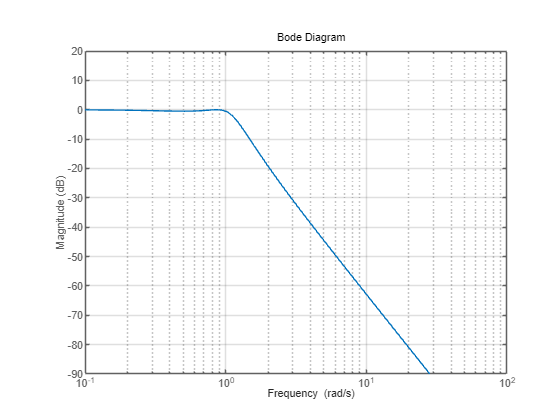

% Define the symbolic variable 's' for Laplace domain
syms s;

% Define the transfer function H(s) based on the provided filter equation
H = (1.1424 / (s^2 + 0.6265 * s + 1.1424)) * (0.6265 / (s + 0.6265));

% Extract numerator and denominator polynomials
[symNum, symDen] = numden(H);

% Create bode plot options
opts = bodeoptions;
opts.Grid = 'on';              % Turn on the grid for better visualization
opts.PhaseVisible = 'off';      % Disable phase plot if not needed

% opts.FreqUnits = 'Hz';

% Set axis limits for magnitude and frequency (modify as per your requirements)
opts.XLim = [0.1 100]; % Frequency range
opts.YLim = [-90 20]; % Magnitude range in dB

% Plot the Bode plot using the symbolic numerator and denominator
bode(sym2poly(symNum), sym2poly(symDen), opts)

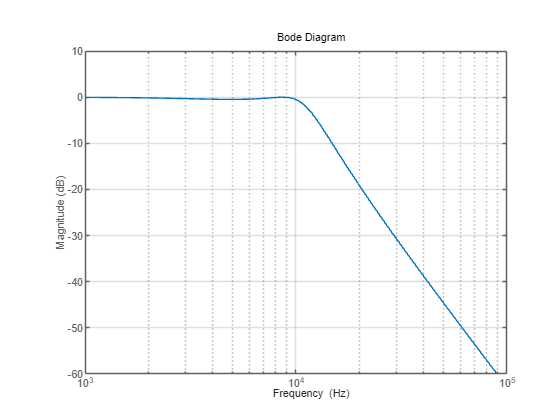

p = s/(2*pi*10*10^3);
num = simplifyFraction((1.1424 / (p^2 + 0.6265 * p + 1.1424)));
den = simplifyFraction(0.6265/(p+0.6265));
H = num*den;
% Extract numerator and denominator polynomials
[symNum, symDen] = numden(H);

% Create bode plot options
opts = bodeoptions;
opts.Grid = 'on';              % Turn on the grid for better visualization
opts.PhaseVisible = 'off';      % Disable phase plot if not needed

opts.FreqUnits = 'Hz';

% Set axis limits for magnitude and frequency (modify as per your requirements)
opts.XLim = [10^3 10^5]; % Frequency range
opts.YLim = [-60 10]; % Magnitude range in dB

% Plot the Bode plot using the symbolic numerator and denominator
bode(sym2poly(symNum), sym2poly(symDen), opts)

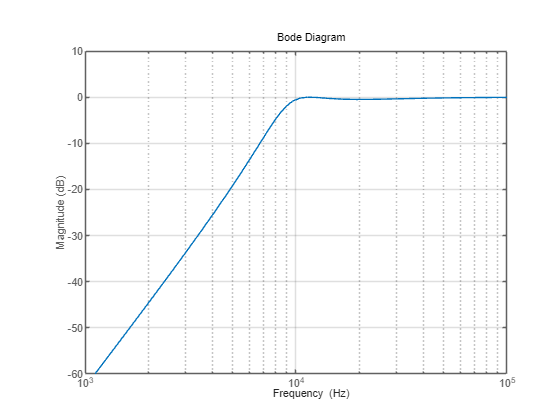

p = (2*pi*10*10^3)/s;
num = simplifyFraction((1.1424 / (p^2 + 0.6265 * p + 1.1424)));
den = simplifyFraction(0.6265/(p+0.6265));
H = num*den;
% Extract numerator and denominator polynomials
[symNum, symDen] = numden(H);

% Create bode plot options
opts = bodeoptions;
opts.Grid = 'on';              % Turn on the grid for better visualization
opts.PhaseVisible = 'off';      % Disable phase plot if not needed

opts.FreqUnits = 'Hz';

% Set axis limits for magnitude and frequency (modify as per your requirements)
opts.XLim = [10^3 10^5]; % Frequency range
opts.YLim = [-60 10]; % Magnitude range in dB

% Plot the Bode plot using the symbolic numerator and denominator
bode(sym2poly(symNum), sym2poly(symDen), opts)